# DynaLearn: DynaSim's learning, memory and intelligent modeling extention tutorial

$@HNXJ \rightarrow For \: ease \: of \: use, \: previously \: created \: DL \: demo \: is \: located \: in:$ 'models/dlDemoPredictivePFC/'

You can still create your own DL model based on your DynaSim struct.

## Getting started

DynaLearn (DL) is an extention for structured use of DynaSim (DS). In this tutorial, we will use it to train a DS model. 

For start, you need to make a DS model (struct). Here are the examples:

### Create DynaSim struct (situational)

close all;clear;clc;
Ne = 24;Ni = 4;Nin = 10;noise_rate = 13;

 If you dont have a saved class file, uncomment one of these lines and remake a DL model in the next section.

% s = NeoCortex(Ne, Ni, Nin, noise_rate); % Basic Neocortex model
% s = dlDemoPING(5, 1, 2, noise_rate); % Basic PING model
s = dlDemoPredictivePFC(Ne, Ni, Nin, noise_rate); % PFC model based on predictive coding

Initialization...
Connecting separate layers and inputs...
Initialization done.


## DynaLearn class

As mentioned above, DL requires a DS struct model or a previously saved DL model thus we should create or load one.

Here we've provided both options for example:

## Create new DL class

Using struct 's' which contains your DS struct, call DL constructor. As it will make 'mex' file for saving runtime later, it may take several minutes to make one. You can save and load your class later.

m = DynaLearn(s, 'models/dlDemoPredictivePFC'); % ~ takes several minutes,  
m.dlSave(); % Save class to its workbench (e.g 'models/dlYourModelName') so for later runs you can skip constructor runtime

#### Dont forget to save your model!

## Load DL Class (previously saved file is required)

In case that you want to just run a basic test or you have a previously saved DL class, continue from here.

m = DynaLearn(); % Create basic instance of DynaLearn



@DS.DL:Creating Dyna model object ... DL object loaded from DynaSim/models/dlBaseModel 
Params.mat file loaded from DynaSim/models/dlBaseModel 

Reinitialized.

@DS.DL:DynaLearn model created.


m = m.dlLoad('models/dlDemoPredictivePFC'); % Load your previously saved copy or demo file

DL object loaded from models/dlDemoPredictivePFC 
Params.mat file loaded from models/dlDemoPredictivePFC 

Reinitialized.


## Simulate and plot example

(This section is runned after first epoch of training)

Params = containers.Map();
Params('tspan') = [0 500];
m.dlUpdateParams(Params);

Updating parameters of models/dlDemoPredictivePFC/solve	Updated.	

m.dlSimulate(); % (optional) simulate it , ~ seconds runtime

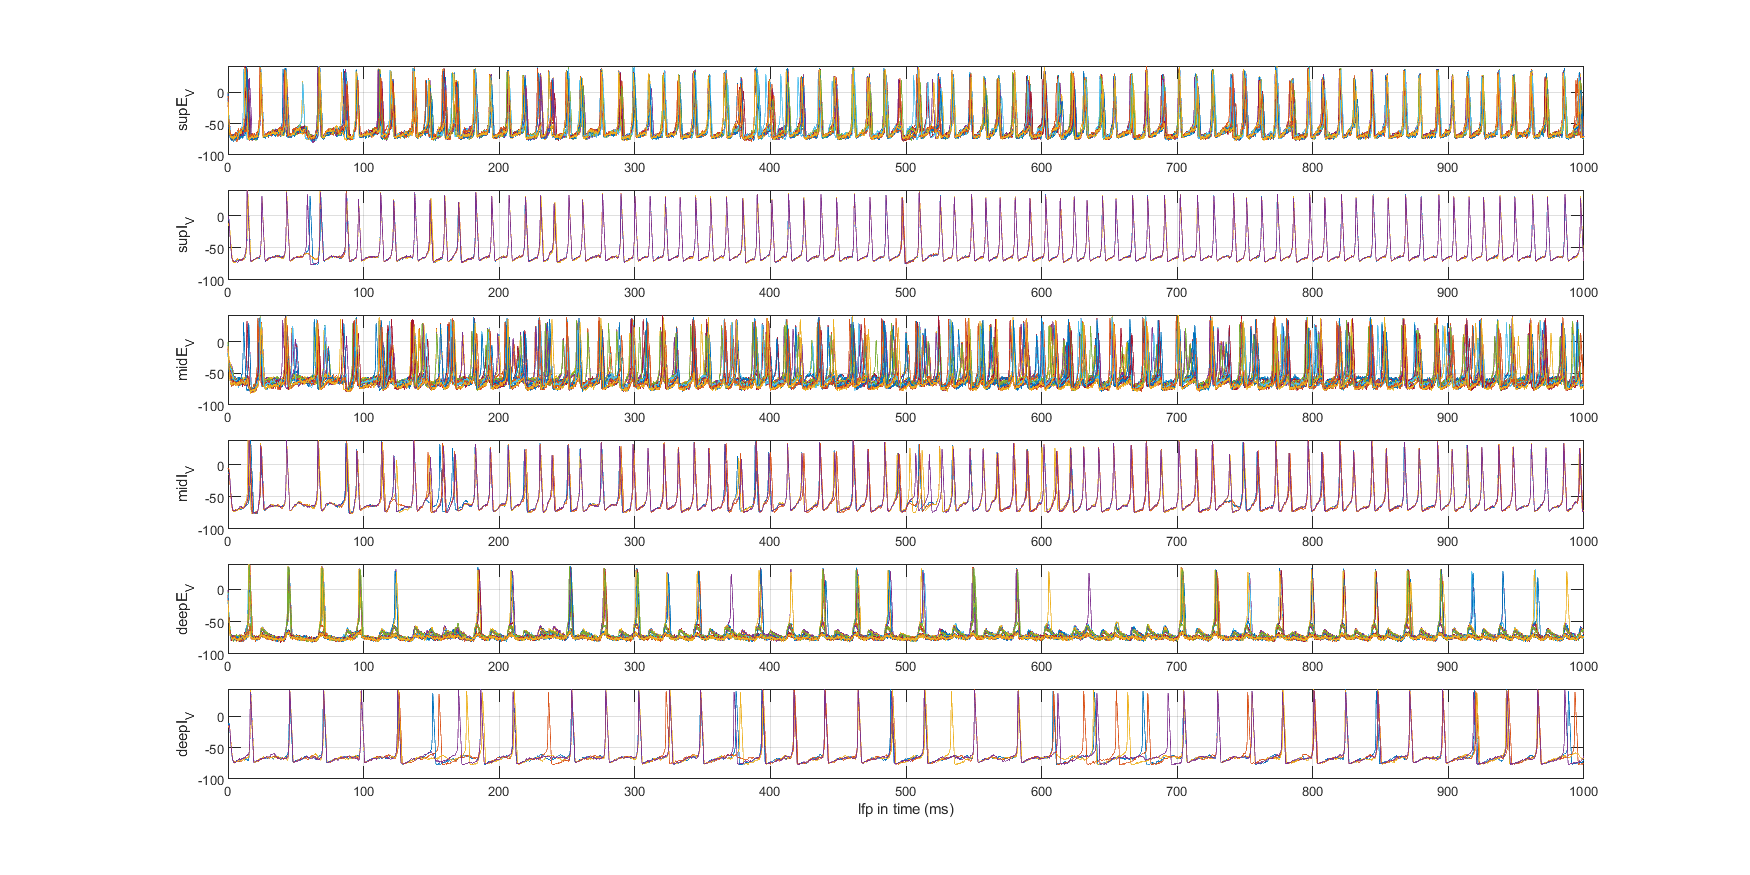

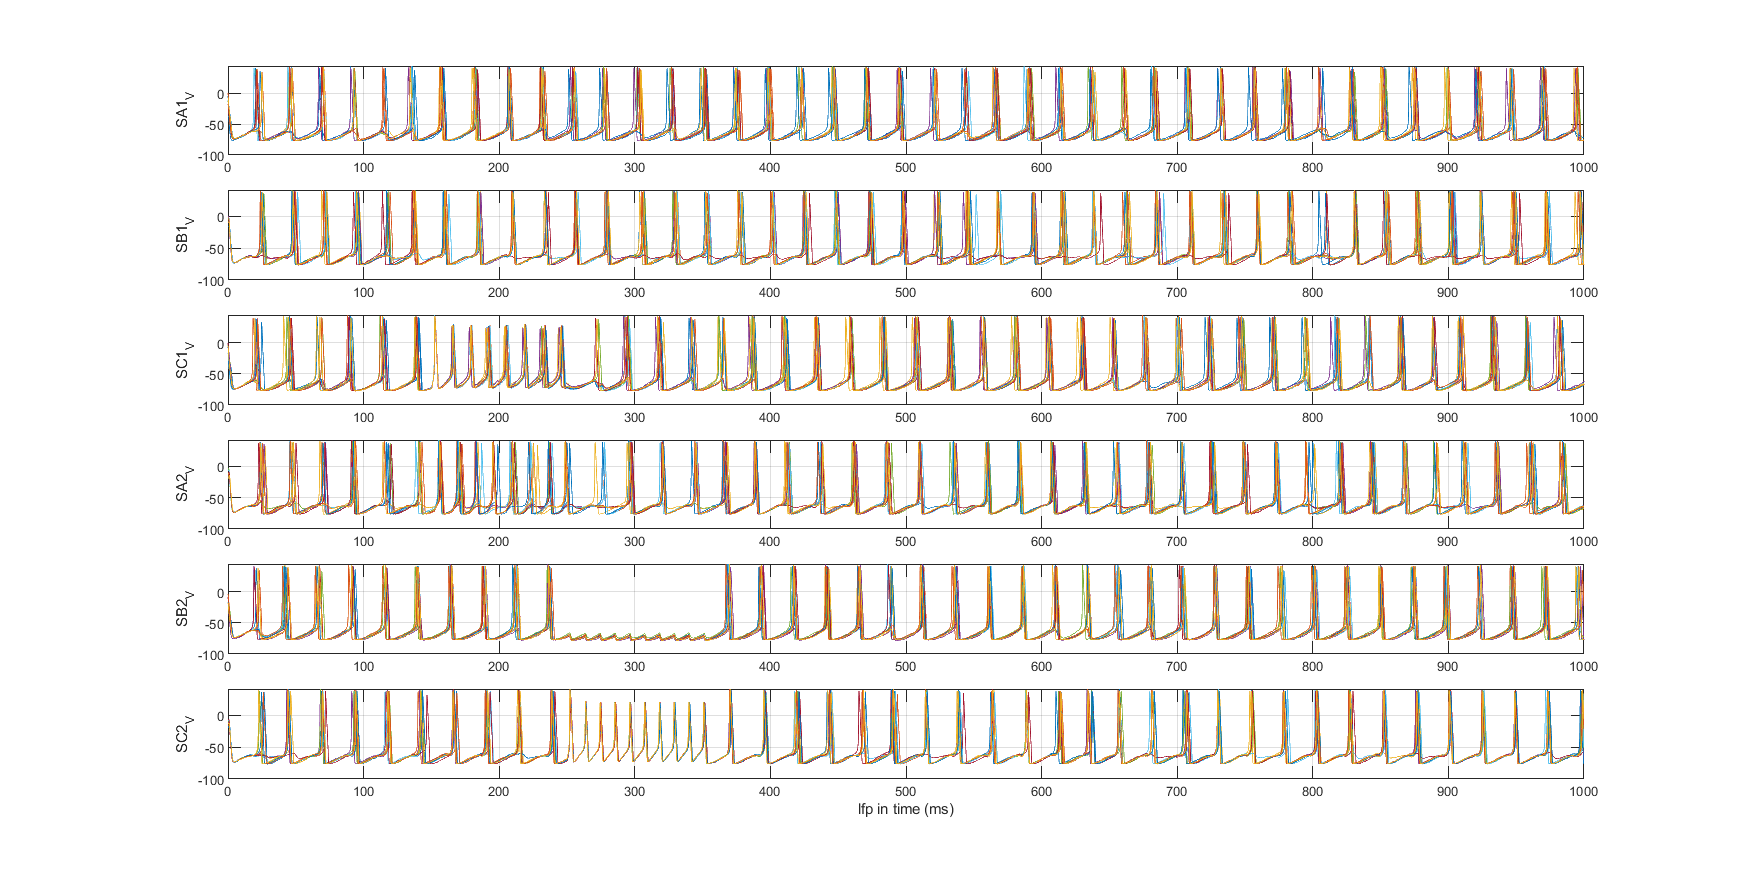

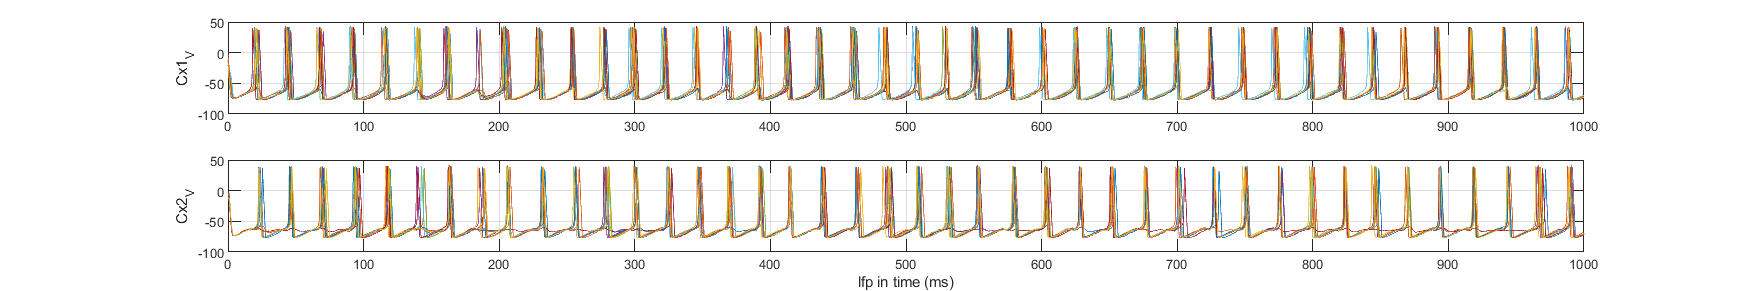

% m.dlPlotAllPotentials('ifr'); % Plot all potential (voltages) as IFR plots ('ifr') or LFP ('lfp').
m.dlPlotAllPotentials('lfp'); % Local field potential

## Changing parameters for training session (Input parameters)

In order to change model or simulation parameters, you should make a 'containers.Map' data structure with matlab; then specify a value for each parameter you want to change.

Our demo example has three different conditions (A, B, C) so we've created three maps:

trialParams1 = containers.Map();
trialParams2 = containers.Map();
trialParams3 = containers.Map();

trialParams1('tspan') = [0 500];
trialParams2('tspan') = [0 500];
trialParams3('tspan') = [0 500];

g_poisson = 6e-4;dc_poisson = 7e5;

trialParams1('SA1_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams1('SA2_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams1('SB1_ctx_iPoisson_DC_poisson') = 0;
trialParams1('SB2_ctx_iPoisson_DC_poisson') = 0;
trialParams1('SC1_ctx_iPoisson_DC_poisson') = 0;
trialParams1('SC2_ctx_iPoisson_DC_poisson') = 0;

trialParams1('SA1_ctx_iPoisson_onset_poisson') = 150;
trialParams1('SA1_ctx_iPoisson_offset_poisson') = 250;
trialParams1('SA2_ctx_iPoisson_onset_poisson') = 250;
trialParams1('SA2_ctx_iPoisson_offset_poisson') = 350;

trialParams1('SB1_ctx_iPoisson_onset_poisson') = 0;
trialParams1('SB1_ctx_iPoisson_offset_poisson') = 0;
trialParams1('SB2_ctx_iPoisson_onset_poisson') = 0;
trialParams1('SB2_ctx_iPoisson_offset_poisson') = 0;

trialParams1('SC1_ctx_iPoisson_onset_poisson') = 0;
trialParams1('SC1_ctx_iPoisson_offset_poisson') = 0;
trialParams1('SC2_ctx_iPoisson_onset_poisson') = 0;
trialParams1('SC2_ctx_iPoisson_offset_poisson') = 0;

trialParams2('SA1_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams2('SA2_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams2('SB1_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams2('SB2_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams2('SC1_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams2('SC2_ctx_iPoisson_DC_poisson') = dc_poisson;

trialParams2('SA1_ctx_iPoisson_onset_poisson') = 250;
trialParams2('SA1_ctx_iPoisson_offset_poisson') = 250;
trialParams2('SA2_ctx_iPoisson_onset_poisson') = 350;
trialParams2('SA2_ctx_iPoisson_offset_poisson') = 350;

trialParams2('SB1_ctx_iPoisson_onset_poisson') = 150;
trialParams2('SB1_ctx_iPoisson_offset_poisson') = 250;
trialParams2('SB2_ctx_iPoisson_onset_poisson') = 250;
trialParams2('SB2_ctx_iPoisson_offset_poisson') = 350;

trialParams2('SC1_ctx_iPoisson_onset_poisson') = 250;
trialParams2('SC1_ctx_iPoisson_offset_poisson') = 250;
trialParams2('SC2_ctx_iPoisson_onset_poisson') = 350;
trialParams2('SC2_ctx_iPoisson_offset_poisson') = 350;

trialParams3('SA1_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams3('SA2_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams3('SB1_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams3('SB2_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams3('SC1_ctx_iPoisson_DC_poisson') = dc_poisson;
trialParams3('SC2_ctx_iPoisson_DC_poisson') = dc_poisson;

trialParams3('SA1_ctx_iPoisson_onset_poisson') = 250;
trialParams3('SA1_ctx_iPoisson_offset_poisson') = 250;
trialParams3('SA2_ctx_iPoisson_onset_poisson') = 350;
trialParams3('SA2_ctx_iPoisson_offset_poisson') = 350;

trialParams3('SB1_ctx_iPoisson_onset_poisson') = 250;
trialParams3('SB1_ctx_iPoisson_offset_poisson') = 250;
trialParams3('SB2_ctx_iPoisson_onset_poisson') = 350;
trialParams3('SB2_ctx_iPoisson_offset_poisson') = 350;

trialParams3('SC1_ctx_iPoisson_onset_poisson') = 150;
trialParams3('SC1_ctx_iPoisson_offset_poisson') = 250;
trialParams3('SC2_ctx_iPoisson_onset_poisson') = 250;
trialParams3('SC2_ctx_iPoisson_offset_poisson') = 350;

## Outputs and targets

DynaLearn.dlTrain(args*) requires two cells containing output and target parameters:

### Output parameters:

parameters indicating which part(s) of the model are its output(s) and how to calculate them. It should be a [Nx4] ((N outputs with their details) 

**Label of output variable** (e.g 'population1_V', 'Layer1_V', 'CustomVariable', ...) 

**Indices of cells in that variable** (e.g [1:4], [1, 3, 11, 21], ...)

**Time interval** (e.g [10 25], [100, 400], ...)

**Calculation method** (e.g 'ifr', 'afr', 'lfp' ...)

### Target parameters

parameters indicating what are goals of the model to calculate reward or error. It should be a [Mx4] (M targets with their details)

**Type of target** ('MSE', 'MAE', 'Compare' which means you want them in an specific order)

**Indices or index of outputs involving in this target** (For non-comparison based target it should be a single number. If it is based on comparison, it should be an array like [2,1,3,5,4] which means target of this model is going to be 'Output2>Output1>Output3>Output5>Output4)

**Target value** (The value that you want this output to generate. For comparison type, it is going to be ignored)

**Target weight** (If there are multiple targets, this value shows how much is the current target's significance.  

outputParams = [{'DeepE_V', 1:4, [200 400], 'afr'}; {'DeepE_V', 5:8, [200 400], 'afr'}; {'DeepE_V', 9:12, [200 400], 'afr'}; {'DeepE_V', 13:16, [200 400], 'afr'}; {'DeepE_V', 17:20, [200 400], 'afr'}];
targetParams1 = [{'MSE', 1, 17, 0.35}; {'MSE', 2, 14, 0.25}; {'MSE', 3, 14, 0.25}; {'Compare', [1, 2, 3], 0, 0.05}; {'Diff', [2, 3], 0, 0.05}]; % A 
targetParams2 = [{'MSE', 2, 17, 0.35}; {'MSE', 1, 14, 0.25}; {'MSE', 3, 14, 0.25}; {'Compare', [2, 1, 3], 0, 0.05}; {'Diff', [1, 3], 0, 0.05}]; % B
targetParams3 = [{'MSE', 3, 17, 0.35}; {'MSE', 2, 14, 0.25}; {'MSE', 1, 14, 0.25}; {'Compare', [3, 1, 2], 0, 0.05}; {'Diff', [1, 2], 0, 0.05}]; % C
% TotalError = 0.25*(O1-18)^2 + 0.25*(O2-8)^2 + 0.25(O3-8)^2 + (ramp(O2-O1) + ramp(O3-O2))*0.15 + abs(O2-O3)*0.05;

## Trial: training script

Lets start training! We've only shown result of last 3 training epochs (equivalent to last 9 trials in here) to reduce training output log.

Each of current available training parameters is explained shortly in the comments.

Consider that RL algorithms usually require hundreds of trials to reach a plausible answer even for a simple model. Here we only used a basic stochastic method to show how to work with it.

dlInputParameters = {trialParams1, trialParams2, trialParams3};
dlTargetParameters = {targetParams1, targetParams2, targetParams3};
dlOutputParameters = outputParams;

dlTrainOptions = containers.Map();
dlTrainOptions('dlEpochs') = 3;
dlTrainOptions('dlBatchs') = 3;
dlTrainOptions('dlLambda') = 0.000004;

dlTrainOptions('dlCheckpoint') = 'true';
dlTrainOptions('dlCheckpointCoefficient') = 1.74; % e.g sqrt(2), sqrt(3), 2, sqrt(5) ... 
dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlLearningRule') = 'BioDeltaRule'; % DeltaRule, BioDeltaRule, RWDelta, ...

dlTrainOptions('dlSimulationFlag') = 1; % Manully turning simulation, on or off (on is default and recommended)
dlTrainOptions('dlOutputLogFlag') = 1; % Autosaving trial outputs, on or off (off is default and recommended) % TODO Output/Random/SameValueProblem
dlTrainOptions('dlOfflineOutputGenerator') = 0; % Just for debugging, generates random outputs based on last outputs. 
dlTrainOptions('dlAdaptiveLambda') = 0; % Adaptive lambda parameter; recommended for long simulations.

dlTrainOptions('dlLambdaCap') = 3e-2; % Only if Adaptive lambda is active, recommended to set a upper-bound (UB) or ignore to use default UB (0.01).
% dlTrainOptions('dlMetaLearningRule') = 'true'; % TODOs!
% dlTrainOptions('dlMetaLearningRule') = 'true'; % TODOs!
% dlTrainOptions('dlMetaLearningRule') = 'true'; % TODOs!

% m.dlResetTraining(); % Reset logs and optimal state error (not the optimal state file)
% m.dlLoadOptimal();  % Load the current optimal state (if exists)
m.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

->Outputs log will be saved.
	Epoch no. 1 (Total iterations for this model : 12)
		Batch no. 1	Updating parameters of models/dlDemoPredictivePFC/solve	Updated.		Error = 52.572077
		Batch no. 2	Updating parameters of models/dlDemoPredictivePFC/solve	Updated.		Error = 7.414341
		Batch no. 3	Updating parameters of models/dlDemoPredictivePFC/solve	Updated.		Error = 45.083231
		Epoch's Average Error = 35.023217, Last lambda = 0.000004
	Epoch no. 2 (Total iterations for this model : 15)
		Batch no. 1	Updating parameters of models/dlDemoPredictivePFC/solve	Updated.		Error = 41.681780
		Batch no. 2	Updating parameters of models/dlDemoPredictivePFC/solve	Updated.		Error = 7.498497
		Batch no. 3	Updating parameters of models/dlDemoPredictivePFC/solve	Updated.		Error = 68.670554
		Epoch's Average Error = 39.283610, Last lambda = 0.000004
Checkpoint file loaded from models/dlDemoPredictivePFC/Optimal 
	Epoch no. 3 (Total iterations for this model : 18)
		Batch no. 1	Updating parameters of models/d

## Errors log plot

Trial by trial and batch mode

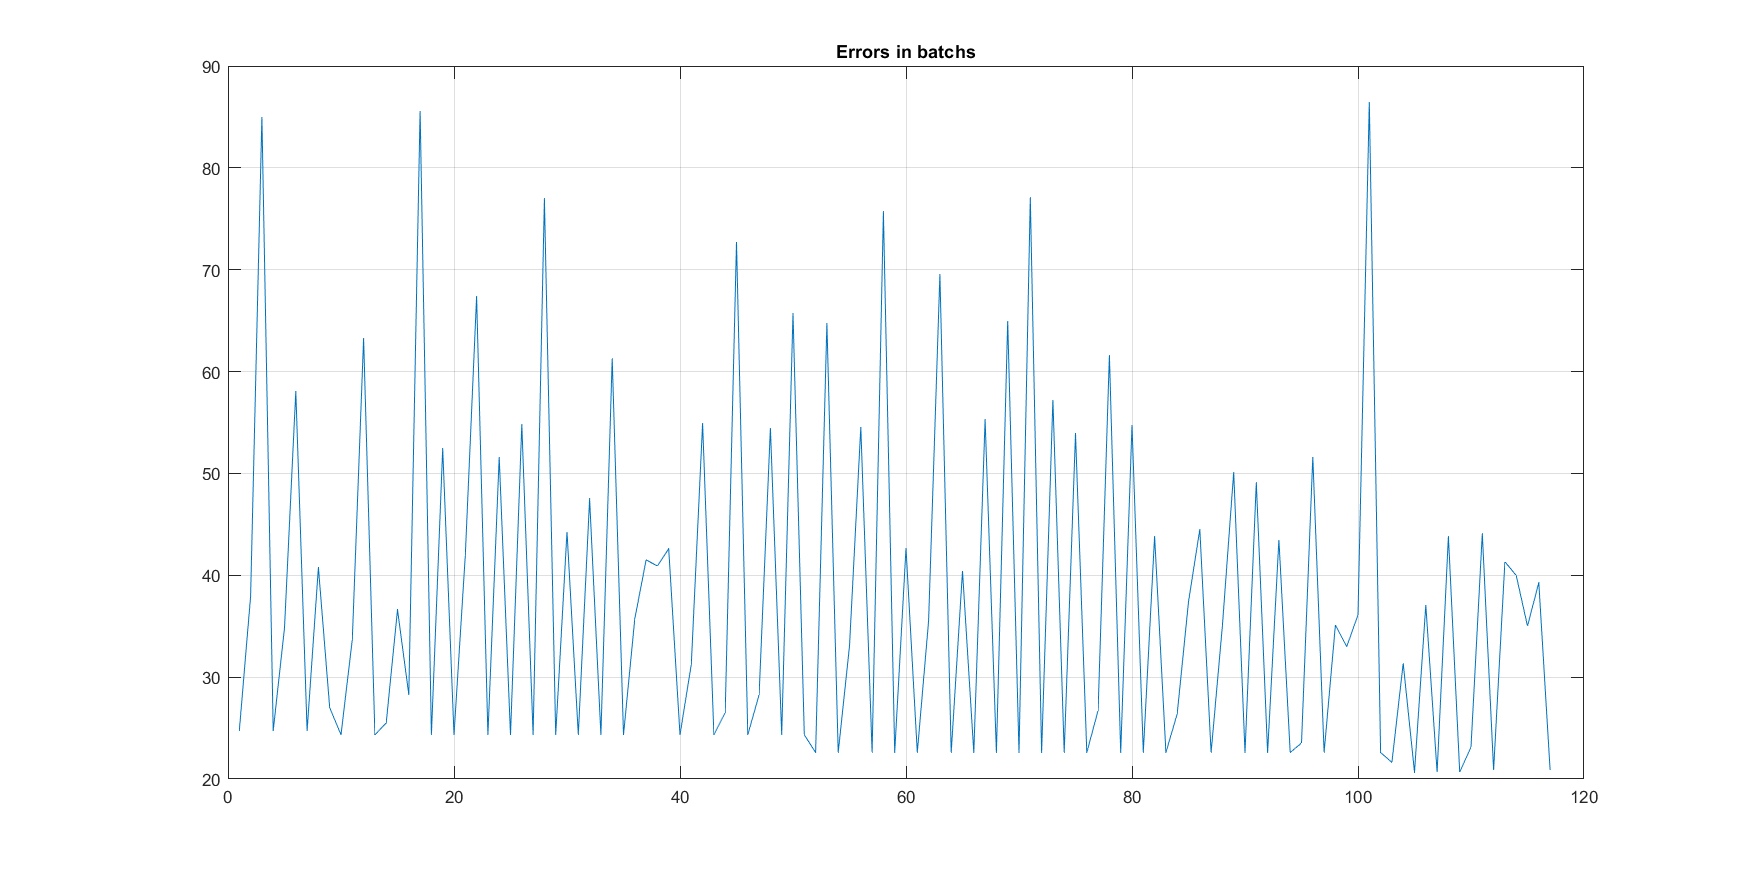

m.dlPlotBatchErrors(3);

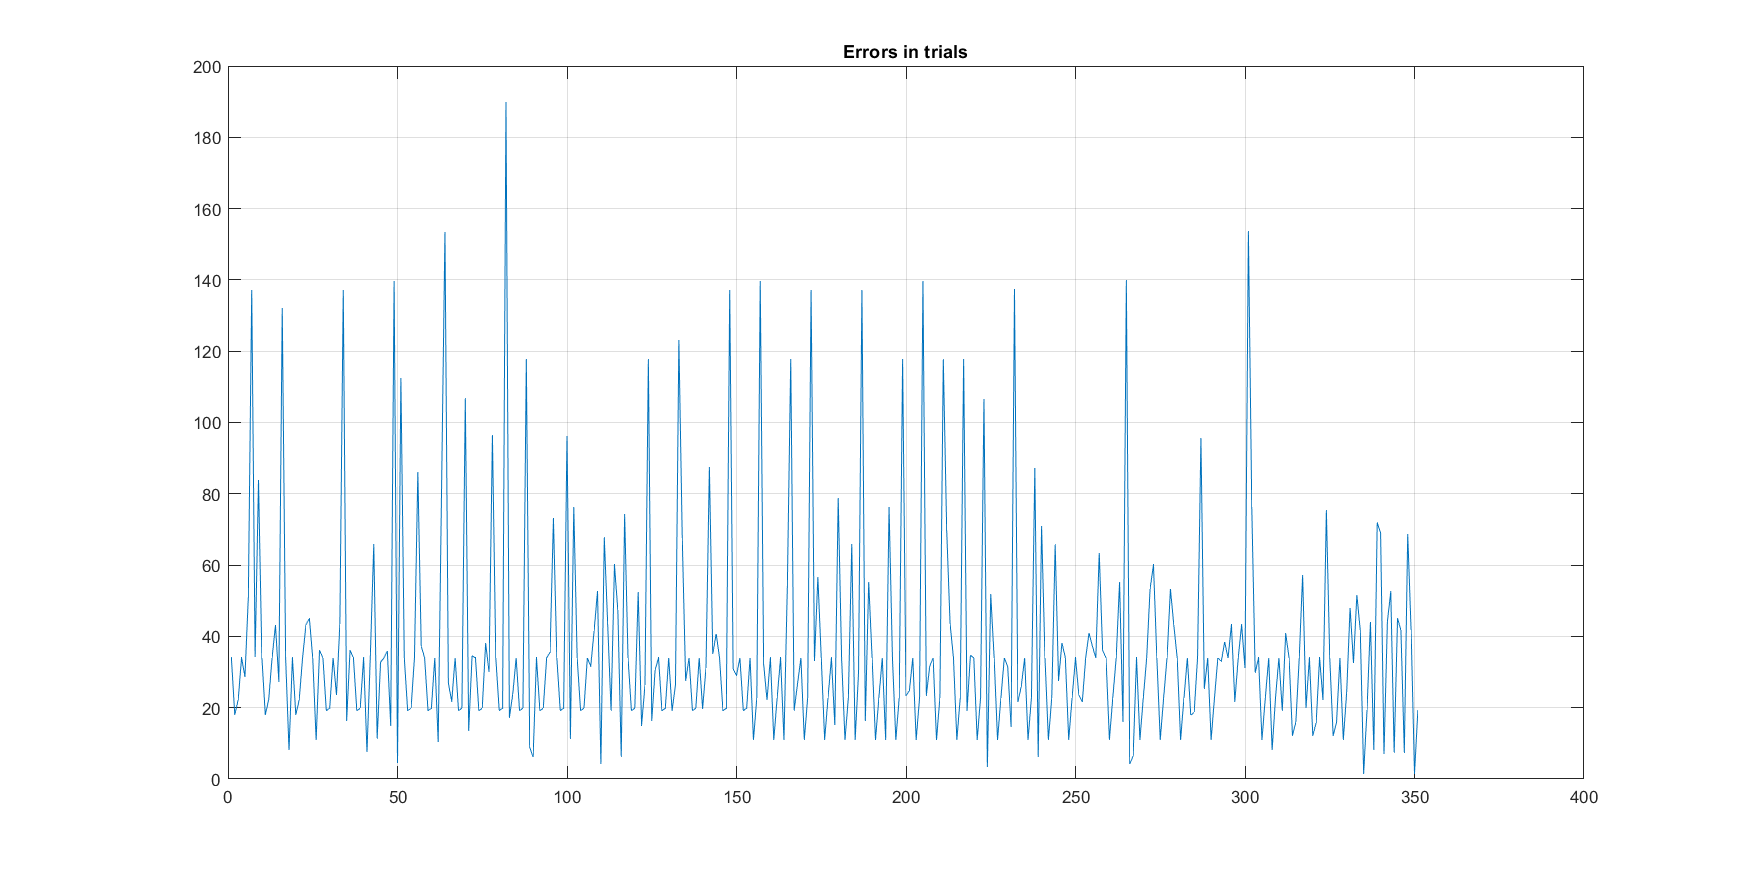

m.dlPlotErrors();

## More details about the training process

We call a full set of trials as "batch". For example, if we have three conditions <A, B, C> (any order) then after running all three possible conditions exacly once, a batch will be completed. Epoch is number of the times that batchs are going to be completed. 

If we have Epochs=5 and Batch=3:

[start] 1: <A, B, C> / 2: <A, B, C> / 3: <A, B, C> / 4: <A, B, C> / 5: <A, B, C> [end]

 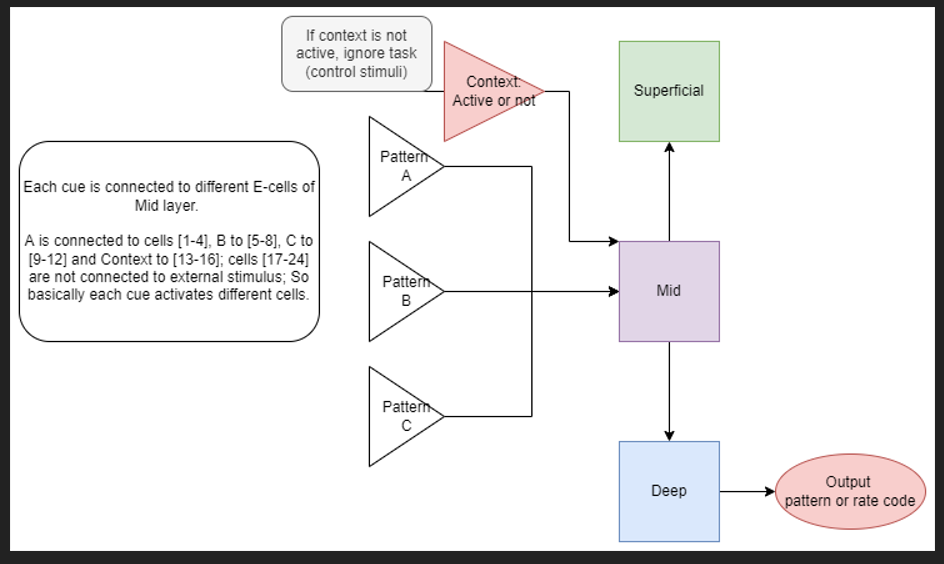

## Run a simulation and plot its result (after basic training)

# A ->delay-> <A, B, C> : A Pred

# ABC-ABC-ABC-ABC => AAAAAAAAA-BCBABCAAB

# A ->delay-> <A, B, C> : A Pred (x50) low DT / high AC

# A/B/C -> delay-> <A, B, C> : ? Unpred high DT / low AC (x50)

If you want to run a single trial without any targets or training, use this:

Or you can use this function for testing the model with another stimuli or input parameters.

tic;
m.dlLoadOptimal();

Checkpoint file loaded from models/dlDemoPredictivePFC/Optimal 


for i = 1:3
    m.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
end


	Single trial running: 
Updating parameters of models/dlDemoPredictivePFC/solve	Updated.	
	Simulation outputs:     [6.8860]    [16.5114]    [6.8990]    [0]    [0]


	Single trial running: 
Updating parameters of models/dlDemoPredictivePFC/solve	Updated.	
	Simulation outputs:     [12.4182]    [17.9375]    [12.3823]    [0]    [0]


	Single trial running: 
Updating parameters of models/dlDemoPredictivePFC/solve	Updated.	
	Simulation outputs:     [16.4159]    [21.9346]    [19.1602]    [0]    [0]



toc;

Elapsed time is 75.220520 seconds.


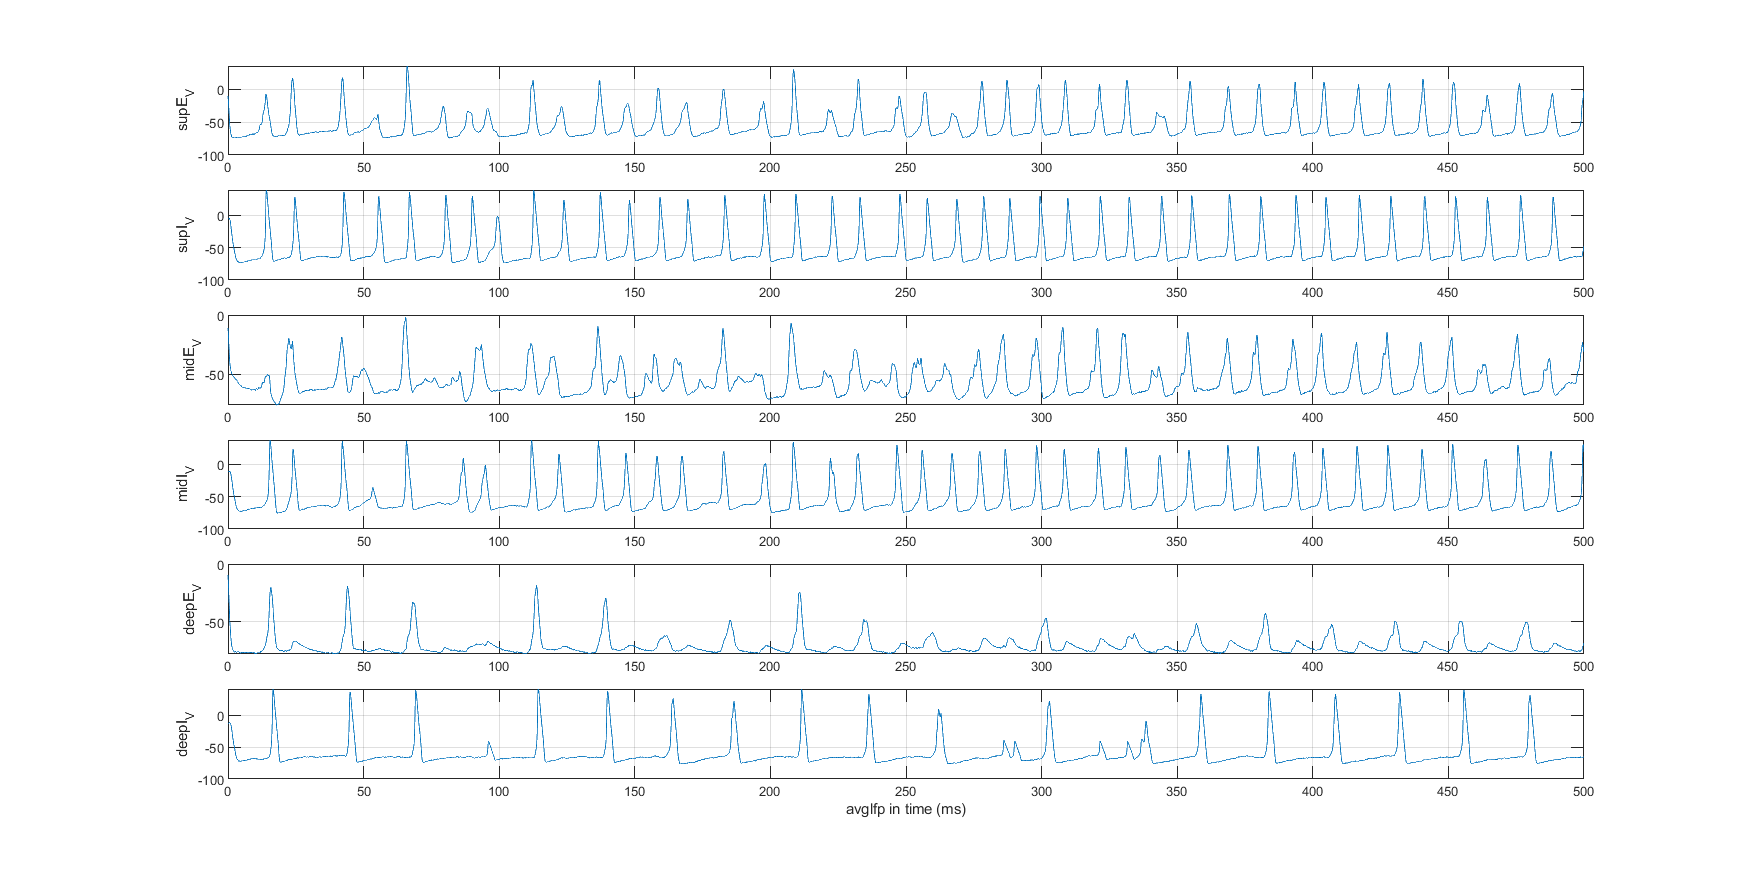

Temp edit for 6 subplots


m.dlPlotAllPotentials('avglfp');

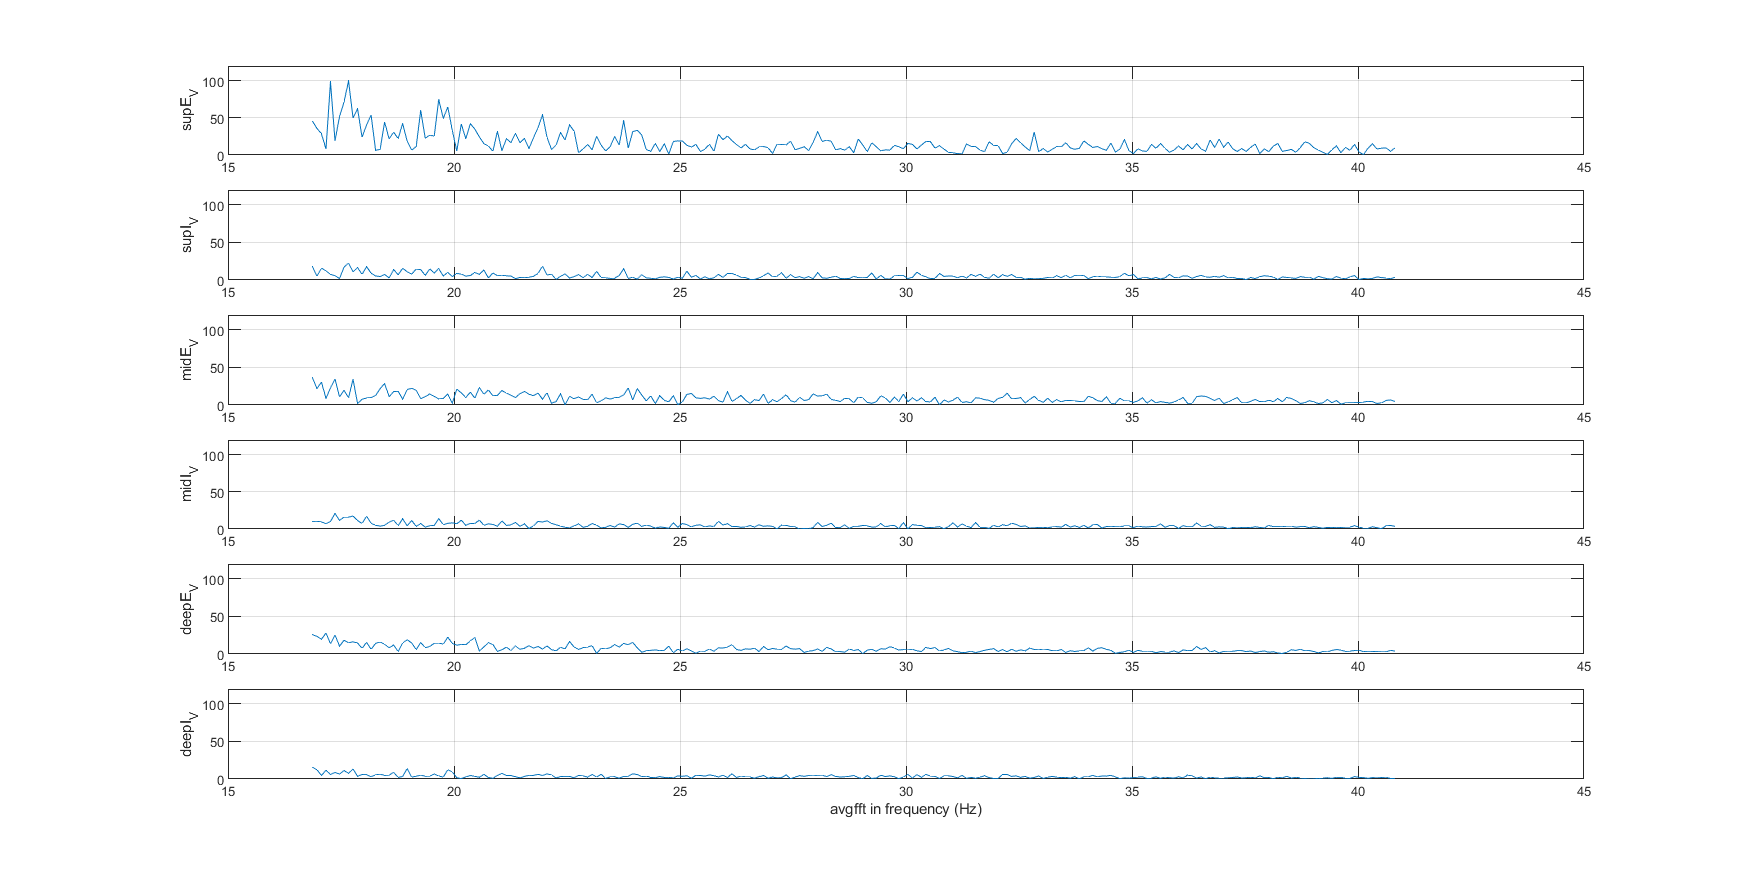

Temp edit for 6 subplots; average fft


opts = containers.Map();
opts("lf") = 16;
opts("hf") = 40;
m.dlPlotAllPotentials('avgfft', opts);

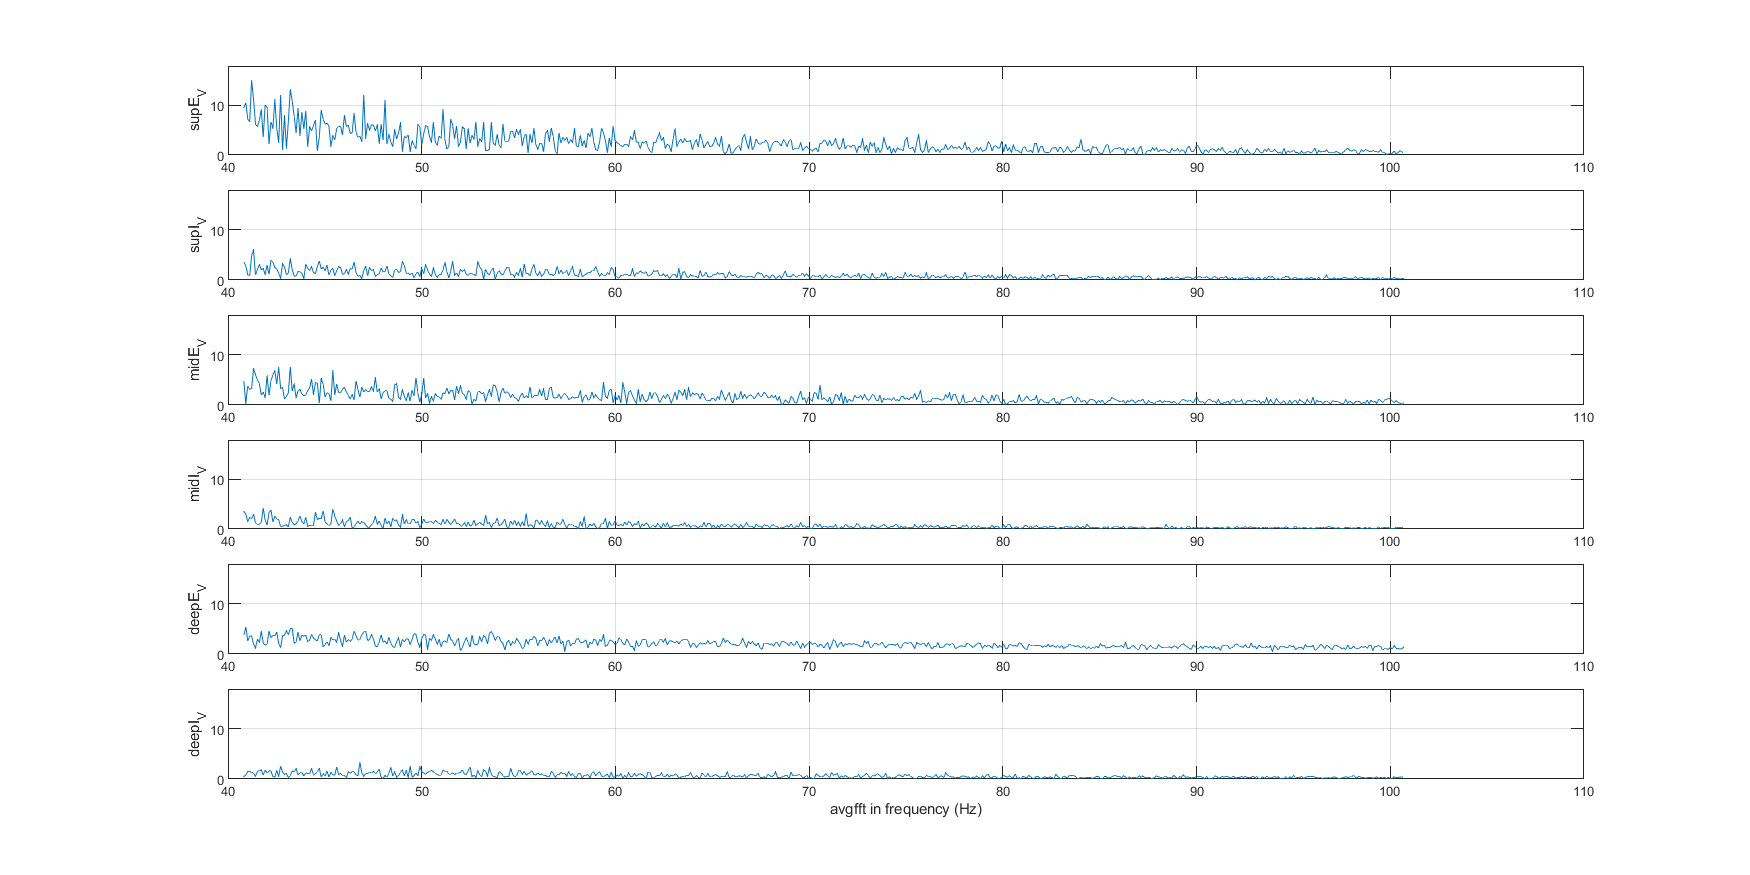

Temp edit for 6 subplots; average fft


opts = containers.Map();
opts("lf") = 40;
opts("hf") = 100;
m.dlPlotAllPotentials('avgfft', opts);

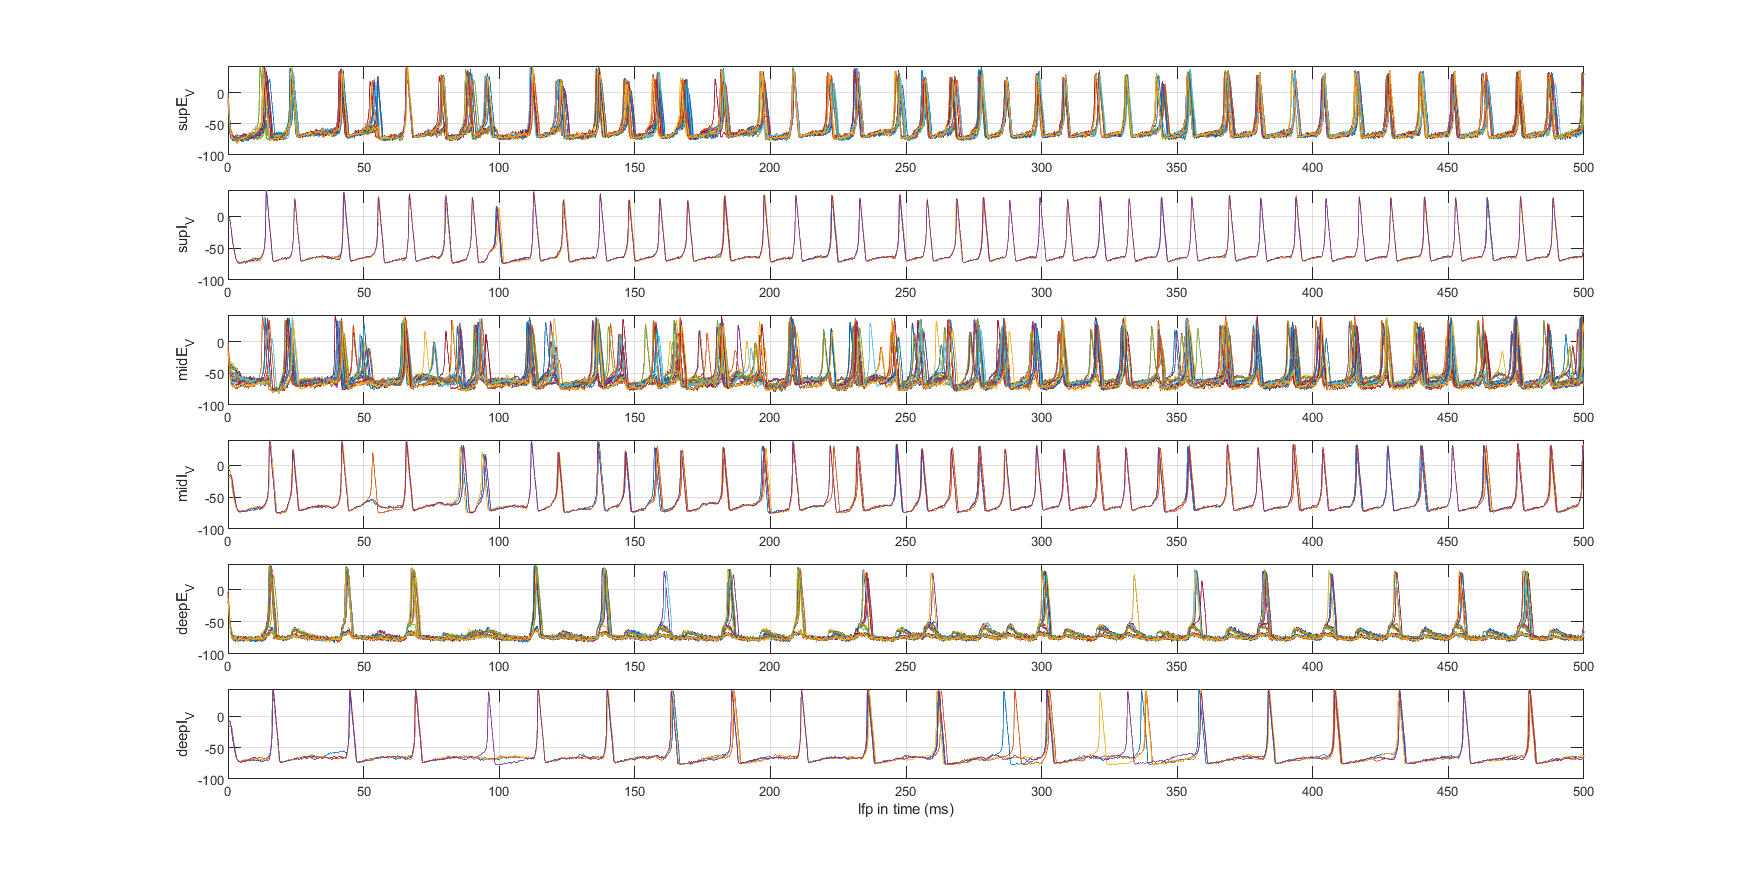

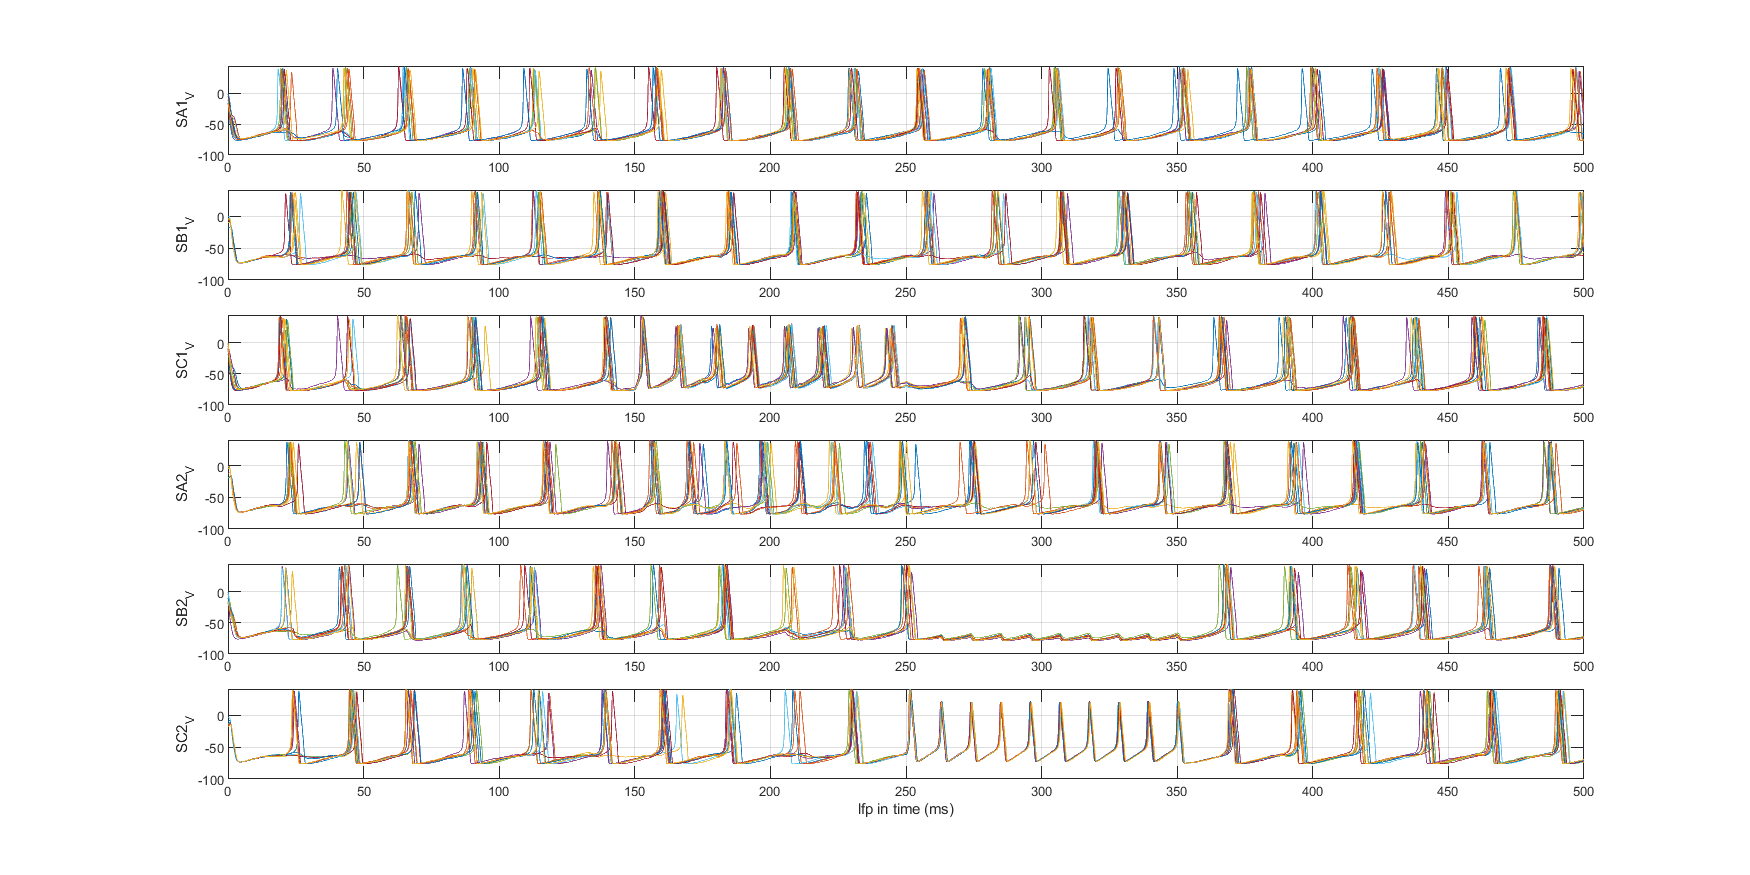

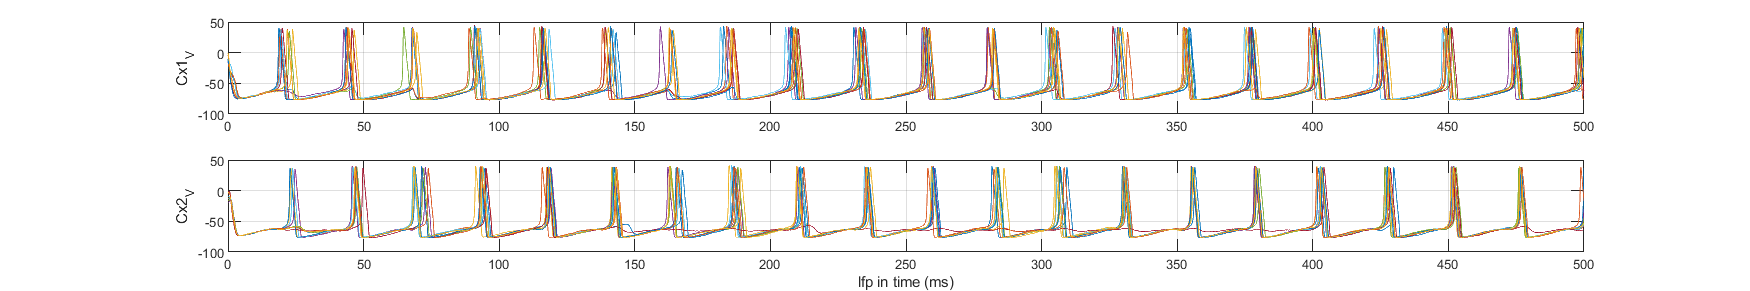

m.dlPlotAllPotentials('lfp');

## End of tutorial 


$$Last \: update: \: May \: 27th, \: 2022$$
